# Mockup of Intro to proposed ciCamera Class

Designed to allow us to think deep thoughts about the proposed class(es) and look at how they might operate.

ciCamera is a class that allows experimentation with computational imaging more directly than the previous "lower-level" scene, oi, sensor, and ip structs. It essentially provides a programmable wrapper on top of them, allowing users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule).

History: Initial Code: D. Cardinal 12/2020

ieInit();
ourCamera = ciCamera(); % probably will pass init args
ourCamera.cmodule = ciCModule(); % default
ourCamera.isp = ipCreate(); % default, maybe:)

Now we'll define our scene

scenePath = 'Cornell_BoxBunnyChart';        
sceneName = 'cornell box bunny chart';
ourScene = ciScene('pbrt', scenePath, sceneName);

% optionally set camera and object motion here
% through parameters/methods of ourScene

% I think the new asset code might still be a bit broken
% so will put this back in later

For the simplest case we ask our camera to take a picture. By default it uses the 'Auto' intent

finalImage = ourCamera.TakePicture(ourScene, 'Auto');

Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.
Reading multispectral data with raw data.


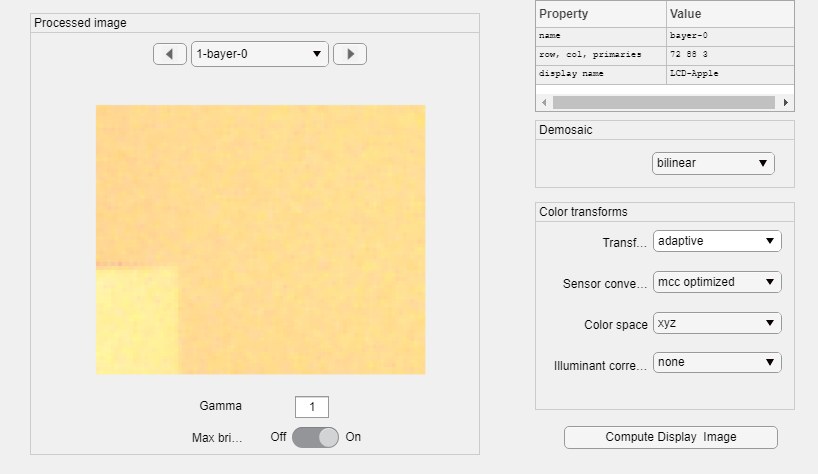

ipWindow(finalImage); % let's see what we got